# 'lathe' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create *povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create scene

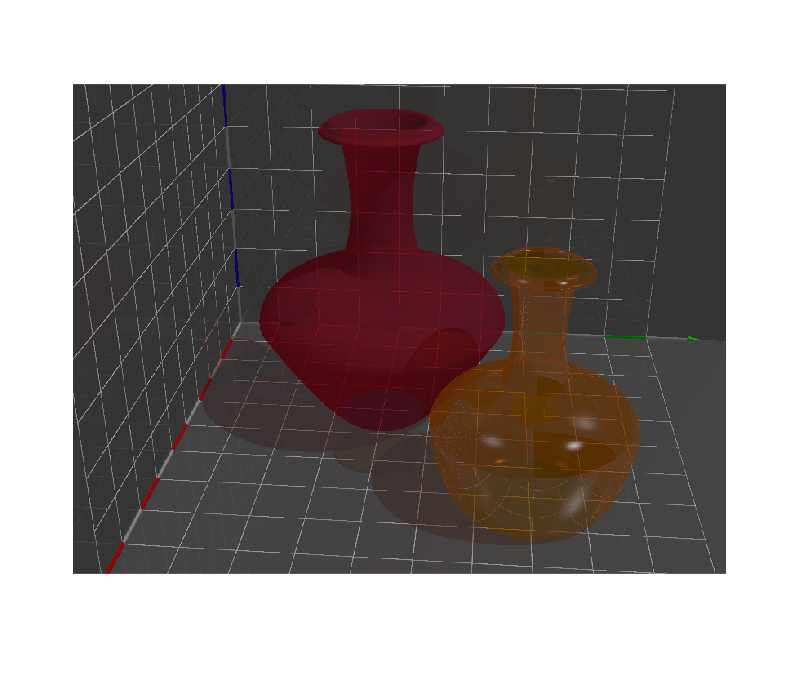

pl.scene_begin('scene_file', 'lathe.pov', 'image_file', 'lathe.png');
pl.include("shapes");

pl.global_settings("assumed_gamma 1");

% Camera
% type: perspective | orthographic | mesh_camera{MESHCAM_MODIFIERS} | fisheye | ultra_wide_angle |
%       omnimax | panoramic | cylinder CylinderType (<int[1..4]>) | spherical
pl.camera('angle', 35, 'location', [23 6 11], 'look_at', [0 4 0], 'type', 'perspective');

% pl.camera('angle', 35, 'location', [12 12 5], 'look_at', [0 1 0]);
% pl.camera('location', [12 12 12], 'look_at', [0 1 0]);
% pl.camera('angle', 35, 'look_at', [0 1 0]);
% pl.camera("angle", 15, 'location', [12 12 12]);

% pl.light();
pl.light('location', [100 200 300], 'color', [0.4 0.4 0.4]);
% pl.light('location', [100 200 300], 'color', [0.4 0.4 0.4], 'shadowless', true);

% pl.light('location', [100 0 0], 'color', [0.1 0.1 0.1]);
% pl.light('location', [0 100 0], 'color', [0.1 0.1 0.1]);
% pl.light('location', [0 0 100], 'color', [0.1 0.1 0.1]);

% Axis textures
% tex_axis_common  = pl.declare("tex_axis_common", pl.texture([0. 0. 0.], "phong 1 reflection {0.10 metallic 0.4}"));
% tex_axis_x = pl.declare("tex_axis_x", pl.texture([1 1 1], "phong 1 reflection {0.10 metallic 0.4}"));
% tex_axis_y = pl.declare("tex_axis_y", pl.texture([0 1 0], "phong 1 reflection {0.10 metallic 0.4}"));
% tex_axis_z = pl.declare("tex_axis_z", pl.texture([0 0 1], "phong 1 reflection {0.10 metallic 0.4}"));

% Axis
% pl.axis();
% pl.axis('length', [5 6 7], 'tex_common', pl.tex_axis_x, 'tex_x', pl.tex_axis_z);
pl.axis('length', [11 11 11]);

% Axis planes textures
% tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.8 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.8 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.8], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));

tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));

% Axis planes
pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_plane_red',  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
pl.plane('normal', [0,1,0], 'distance', 0, 'texture', tex_plane_green, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane_blue,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);

% Grid
tex_grid_gray  = pl.declare("tex_grid_gray",  pl.texture('pigment', [0.5 0.5 0.5], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
tex_grid_red   = pl.declare("tex_grid_red",   pl.texture('pigment', [1.0 0.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
tex_grid_green = pl.declare("tex_grid_green", pl.texture('pigment', [0.0 1.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
tex_grid_blue  = pl.declare("tex_grid_blue",  pl.texture('pigment', [0.0 0.0 1.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));

% pl.grid_2D('width', 10, 'height', 10,                      'translate', [5 0 5], 'texture_odd', tex_grid_green, 'texture_even', tex_grid_gray);
% pl.grid_2D('width', 10, 'height', 10, 'rotate', [ 0 0 90], 'translate', [0 5 5], 'texture_odd', tex_grid_blue,  'texture_even', tex_grid_gray);
% pl.grid_2D('width', 10, 'height', 10, 'rotate', [90 0  0], 'translate', [5 5 0], 'texture_odd', tex_grid_red,   'texture_even', tex_grid_gray);

pl.grid('width', 10, 'height', 10, 'radius', 0.01,                     'translate', [5 0 5]);
pl.grid('width', 10, 'height', 10, 'radius', 0.01,'rotate', [ 0 0 90], 'translate', [0 5 5]);
pl.grid('width', 10, 'height', 10, 'radius', 0.01,'rotate', [90 0  0], 'translate', [5 5 0]);

% Objects textures
tex_red   = pl.declare("tex_red",   pl.texture('pigment', [1 0 0], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
tex_green = pl.declare("tex_green", pl.texture('pigment', [0 1 0], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
tex_blue  = pl.declare("tex_blue",  pl.texture('pigment', [0 0 1], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
tex_pink  = pl.declare("tex_pink",  pl.texture('pigment', [8 2 3], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));

% linear_spline | quadratic_spline | cubic_spline | bezier_spline
pl.lathe('points', [0.00 0.00; 0.22 0.00; 0.62 0.54; 0.21 0.83; 0.19 1.46; 0.29 1.50; 0.26 1.53],...
        'spline_type', 'quadratic_spline',...
        'sturm', true,...
        'texture', 'Ruby_Glass',...
        'scale', [4 4 4], 'rotate', [ 90 0 0], 'translate', [4 4 0]);

pl.lathe('points', [0.00 0.00; 0.42 0.00; 0.62 0.54; 0.21 0.83; 0.19 1.46; 0.29 1.50; 0.26 1.53],...
        'spline_type', 'quadratic_spline',...
        'sturm', true,...
        'texture', 'Orange_Glass',...
        'scale', [3 3 3], 'rotate', [ 90 0 0], 'translate', [7 7 0]);

pl.scene_end();
img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 7.785981 seconds.
